## Sniffing Data Analysis

This live script includes the methods used to perfrom analysis on the HybridSniff model

### The HybridSniff Model

The model is an LSTM-CNN model based, speach recognition model with resnet backbone.

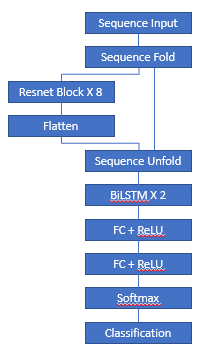

*figure 1: Model architectue*

Step 1: Load the model

load('HybridSniffModel.mat')
%uncomment to see more model details
% analyzeNetwork(net) 

### Preprocess data

The model's input is a sniffing recordings taken at 250kHz and downsampled to 1kHz

load('sniff_vector_250k.mat')
original_sampling_rate = 2.5e5;
new_sampling_rate = 1000;
sniff_vector_1k = downsample_audio(sniff_vector_250k,original_sampling_rate, new_sampling_rate);

The downsampled vector is reshaped and goes a wavelet transformations to create a squence of 81x151 spectrograms. Each spectrogram represents 1 time-bin with duration of 30 ms

audio_vector = sniff_vector_1k;
audio_len_bin = 2000;
output_len_bin = 500;
window_len_bin = 0;
overlap_len_bin = 130;



data.vector={reshape0(audio_vector,[audio_len_bin,-1],'pad',0)};
data.labels = [];


[featuresCell,~] = prepare_files(...
    data,...
    audio_len_bin, ...
    output_len_bin, ...
    window_len_bin, ...
    overlap_len_bin);

### Run inference on model

predictions = predict(HybridSniff, featuresCell);

### Visualize the results

To visualize the results, you must download and install the HybridMouse repository

HybridMuse Version 2.0


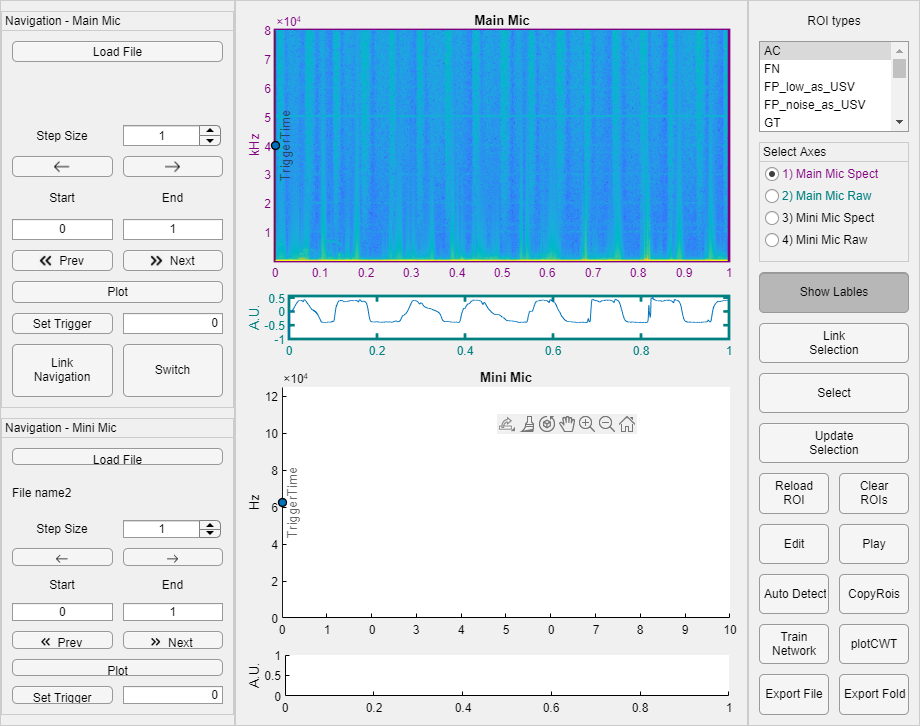

obj = audioClip;
obj.emptyFlag = false;
obj.vec = sniff_vector_250k;
obj.fs = original_sampling_rate;
obj.refresh_audioLen;

config.th = 0.35;
config.gaussian = 0.1;

obj = convert_to_obj(obj,predictions,[],config);
obj.explore